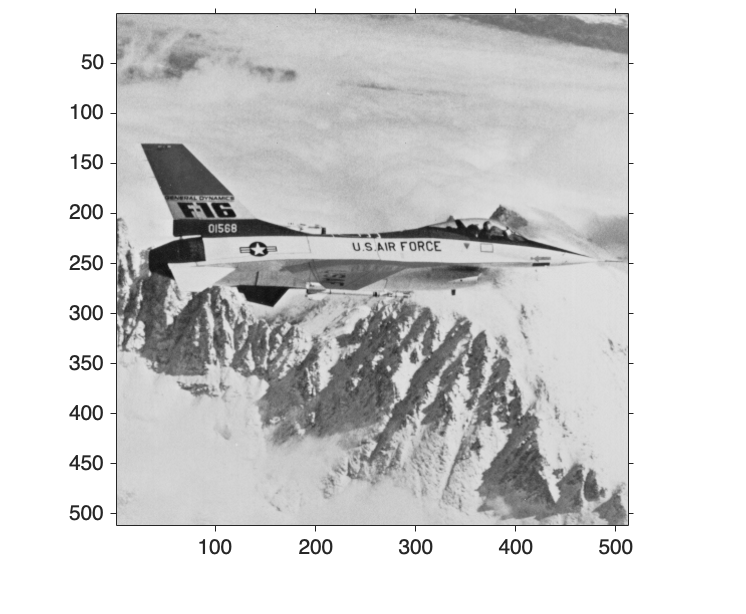

img = imread("../images/jetplane.tif");
ref = imref2d(size(img));
imshow(img, ref)

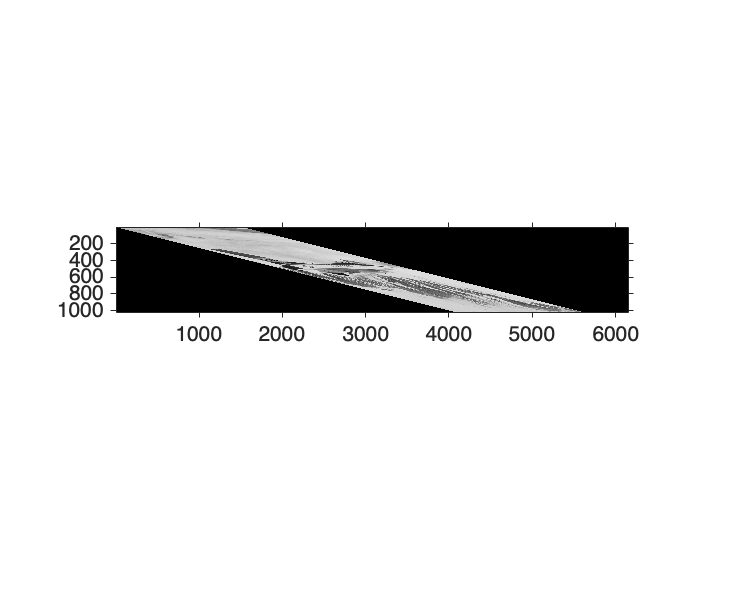

scale = [3 0 0;
         0 2 0;
         0 0 1];
shear = [1 4 0;
         0 1 0;
         0 0 1];
% The transformation matrices should be multiplied from right to left step
% by step.
tform = affinetform2d(shear * scale);
% Adjust view board
ScaleShearRef = ref;
ScaleShearRef.XWorldLimits(2) = ScaleShearRef.XWorldLimits(2) * 12;
ScaleShearRef.YWorldLimits(2) = ScaleShearRef.YWorldLimits(2) * 2;
[ScaleShearImg, ScaleShearRef] = imwarp(img, tform, "OutputView", ScaleShearRef);
imshow(ScaleShearImg, ScaleShearRef)

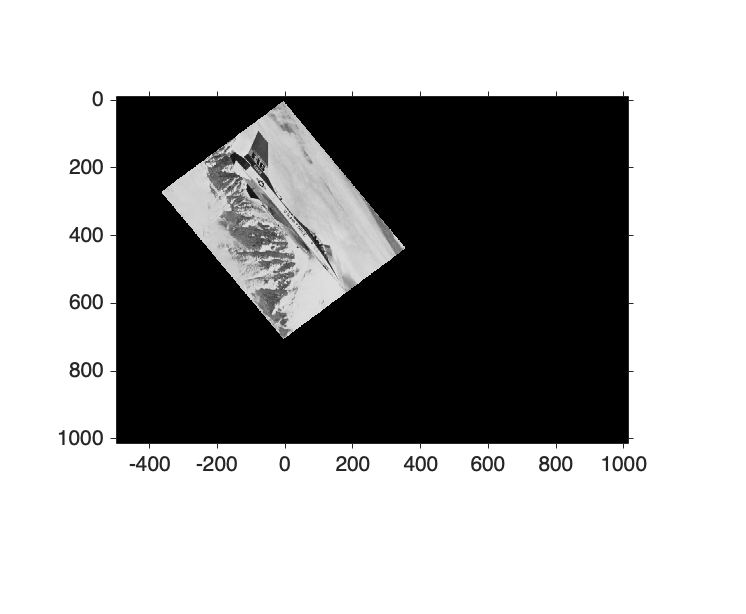

translate = [1 0 -2;
             0 1 5;
             0 0 1];
rotate = [cosd(45) -sind(45) 0;
          sin(45) cos(45) 0;
          0 0 1];
tform = affinetform2d(rotate * translate);
TranslateRotateRef = ref;
TranslateRotateRef.XWorldLimits(1) = TranslateRotateRef.XWorldLimits(1)-500;
TranslateRotateRef.XWorldLimits(2) = TranslateRotateRef.XWorldLimits(2)+500;
TranslateRotateRef.YWorldLimits(1) = TranslateRotateRef.YWorldLimits(1)-10;
TranslateRotateRef.YWorldLimits(2) = TranslateRotateRef.YWorldLimits(2)+500;
[TranslateRotateImg, TranslateRotateRef] = imwarp(img, tform, "OutputView", TranslateRotateRef);
imshow(TranslateRotateImg, TranslateRotateRef)